%dove sono i frame
imageFolder = imageDatastore("frameTest2\");
%le immagini si portano in bianco e nero per velocizzare la computazione

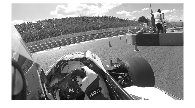

%carico prima immagine
I = 1; % first frame idx
Im1 = readimage(imageFolder, I); 
Im1 = im2gray(Im1);
imshow(Im1)

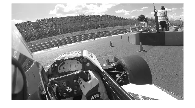

%carico seconda immagine
nextI = 2;
Im2 = readimage(imageFolder, nextI);
Im2 = im2gray(Im2);
imshow(Im2)

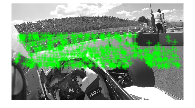

%raccolta delle feature delle due immagini
[feat1, valid1] = dammiFeat(Im1);
[feat2, valid2] = dammiFeat(Im2);
imshow(Im1)
hold on
plot(valid1, 'ShowScale',false)
hold off

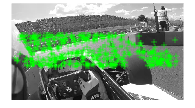

imshow(Im2)
hold on
plot(valid2, 'ShowScale',false)
hold off

%creazione oggetto camera, servirà poi per la triangolazione delle immagini
%(NB i valori di distanza foocale e principal point sono di default, non sono il massimo ma sono tutto quello che abbiamo)
vidObj = VideoReader('videoTest\Formula Student East 2022 - AutoX (Alumni Cup) ⧸ Rennteam Stuttgart F0711-11 onboard.mp4');
vidHeight = vidObj.Height;
vidWidth = vidObj.Width;
vidFrames = vidObj.Framerate;
vidDuration = vidObj.Duration;

focalLength = mean([vidHeight vidWidth])*1; % lunghezza focale in pixel
principalPoint = [vidHeight vidWidth]/2; % punto principale in pixel

intrinsics = cameraIntrinsics(focalLength, principalPoint, size(Im1,[1,2]));

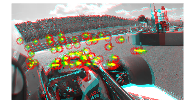

%matching dei punti tra le due immagini
indexPairs = matchFeatures(feat1,feat2);
matchedPoints1 = valid1(indexPairs(:,1),:);
matchedPoints2 = valid2(indexPairs(:,2),:);
figure; 
%il plot è fatto in modo tale che si vede la seconda immagine e in
%trasparenza la prima
showMatchedFeatures(Im1,Im2,matchedPoints1,matchedPoints2)

%vediamo se la scena è planare o meno computando la sua omografia e la
%matrice fondamentale dell'immagine
[H, punteggioOmo, inliersOmo] = omografia(matchedPoints1, matchedPoints2);
[F, punteggioFM, inliersFM] = fm(matchedPoints1, matchedPoints2);

ratio = punteggioOmo/(punteggioOmo + punteggioFM)

ratio = single
0.3592

function [F, punteggio, inliersId] = fm(match1, match2)
[F, inliers] = estimateFundamentalMatrix(match1, match2);

inliers1 = match1(inliers);
inliers2 = match2(inliers);

inliersId = find(inliers);

loc1 = inliers1.Location;
loc2 = inliers2.Location;

line1   = epipolarLine(F', loc2);
error2in1 = (sum([loc1, ones(size(loc1, 1),1)].* line1, 2)).^2 ./ sum(line1(:,1:2).^2, 2);
line2   = epipolarLine(F, loc1);
error1in2 = (sum([loc2, ones(size(loc2, 1),1)].* line2, 2)).^2 ./ sum(line2(:,1:2).^2, 2);

outlierThreshold = 4;

punteggio = sum(max(outlierThreshold-error1in2, 0)) + sum(max(outlierThreshold-error2in1, 0));
end

function [H,punteggio, inliersId] = omografia(matchedPoints1, matchedPoints2)
[H, inliers] = estgeotform2d(matchedPoints1,matchedPoints2,"projective");

inliers1 = matchedPoints1(inliers);
inliers2 = matchedPoints2(inliers);

inliersId = find(inliers);

loc1 = inliers1.Location;
loc2 = inliers2.Location;

xy1in2 = transformPointsForward(H, loc1);
xy2in1 = transformPointsForward(H, loc2);
err1in2 = sum((loc2 - xy1in2).^2, 2);
err2in1 = sum((loc1 - xy2in1).^2, 2);

outlierThreshold = 6;

punteggio = sum(max(outlierThreshold-err1in2, 0)) + sum(max(outlierThreshold-err2in1, 0));
end

Funzione per ottenimento punti, si prende un numero aribitrario di punti e da essi si prendono quelli di interesse maggiore

function [feature, validPoint] = dammiFeat(currIm)
%roi è il valore che indica la porzione di immagine in cui cercare riferimenti,
%inutile vedere anche il cielo o la macchina perciò riduco il range
roi = [1 200 1280 300];
orbFeat = detectORBFeatures(currIm, ROI=roi);

n = 1000;
point = selectUniform(orbFeat, n, size(currIm));

[feature, validPoint] = extractFeatures(currIm,point);
end